clc
clear
addpath("srcs\all_func\");

Import data store and Label

imgDs = imageDatastore("srcs\imgs\", "IncludeSubfolders", true, "LabelSource", "foldernames");
%split
[trainDs, testDs] = splitEachLabel(imgDs, 8, "randomized");

pro_train = transform(trainDs, @myfilt);
pro_test = transform(testDs, @myfilt);
eval_label = testDs.Labels;
train_label = arrayDatastore(trainDs.Labels);
test_label = arrayDatastore(testDs.Labels);
pro_train = combine(pro_train, train_label);
pro_test = combine(pro_test, test_label);

test = readimage(trainDs, 1);
test = myfilt(test);
size(test)

ans =    224   224     3


Import the model for transfer learning

load srcs\all_func\lgraph.mat;  
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",10);

Import Model

load srcs\all_func\aneuNetRM.mat;

Train model

[aneuNet, info] = trainNetwork(pro_train, lgraph, opts)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:01:06 |       50.00% |       1.0741 |          0.0010 |
|      10 |          10 |       00:06:53 |      100.00% |       0.0782 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


aneuNet =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'classoutput'}


info = struct with fields:
              TrainingLoss: [1.0741 0.7339 0.4471 0.3578 0.3807 0.2725 0.1957 0.1575 0.0826 0.0782]
          TrainingAccuracy: [50 50 81.2500 81.2500 75 87.5000 93.7500 93.7500 100 100]
             BaseLearnRate: [0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010]
    OutputNetworkIteration: 10


Predict

[pred, info] = classify(aneuNet, pro_test);

Evaluation

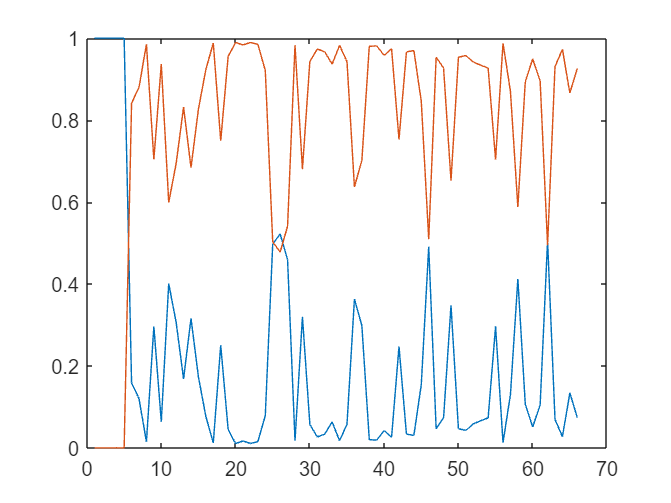

plot(info);

%calculate accuracy
num_correct = nnz(pred == eval_label);
accuracy = num_correct / numel(eval_label)

accuracy = 0.9697

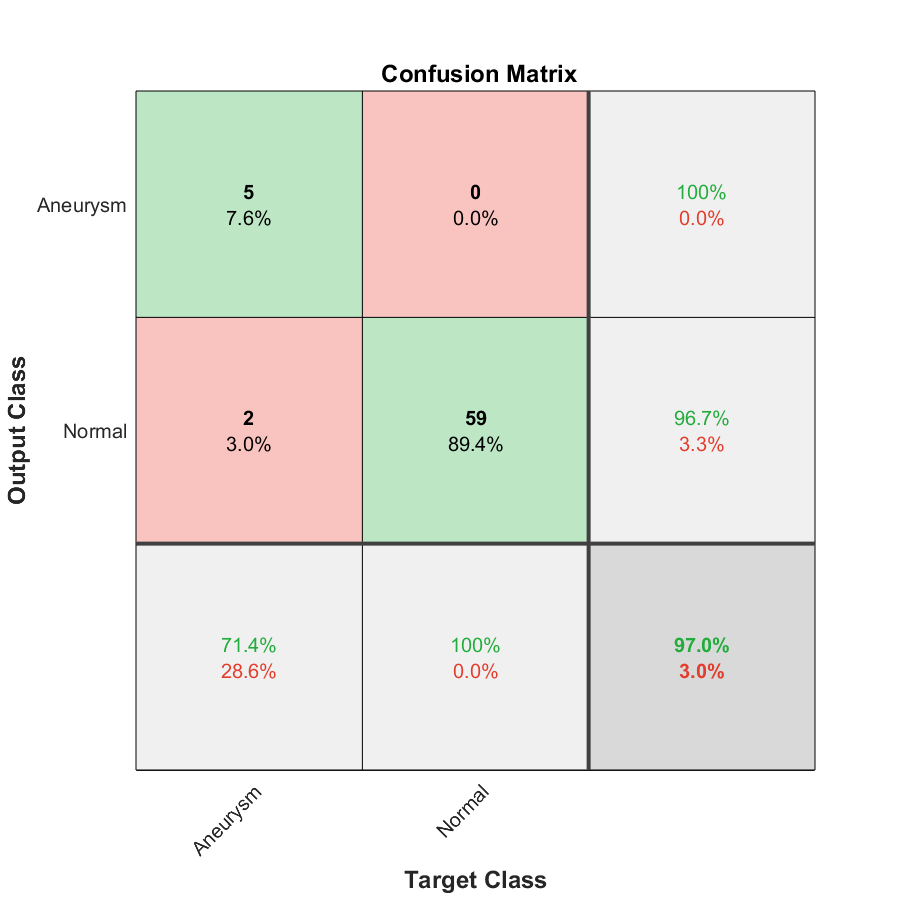

plotconfusion(pred, eval_label);

preprocesing func

function res = myfilt(img)
img = AllFilters.KmeanFilter(img);
img = AllFilters.rmlarger(img, 200);
img = imresize(img, [224, 224]);
res = cat(3, img, img ,img);
end